# Laborator 6

## Problema 1

### a) $t_f =3,\theta_0 =\frac{\pi }{3},v_0 =0,l=1,m=1$

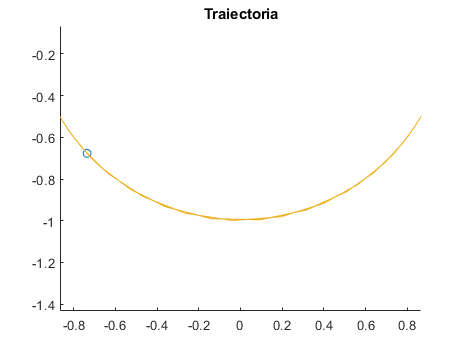

g=9.8; l=1; t_0=0; t_f=3; v_0=0; m=1;
theta_0=pi/3; Dtheta_0=v_0/l;

syms theta(t)

interval_timp=[t_0 t_f];
val_initiale=[theta_0 Dtheta_0];
f=-g/l.*sin(theta);
theta_eq=diff(theta,t,2)==f;
[P]=odeToVectorField(theta_eq);
M=matlabFunction(P,'vars',{'t','Y'});
[t,S]=ode45(M,interval_timp,val_initiale);
theta=S(:,1);
r_x=l.*cos(theta);
r_y=l.*sin(theta);
comet(r_y,-r_x)
title("Traiectoria")
axis equal

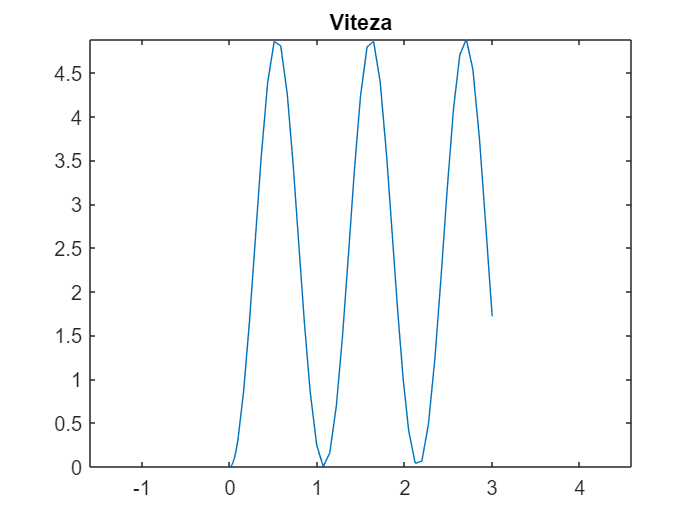


v_r=zeros(69,1);
v_t=l*S(:,2);

v=v_r.^2+v_t.^2;

plot(t,v.^1/2)
title("Viteza")
axis equal

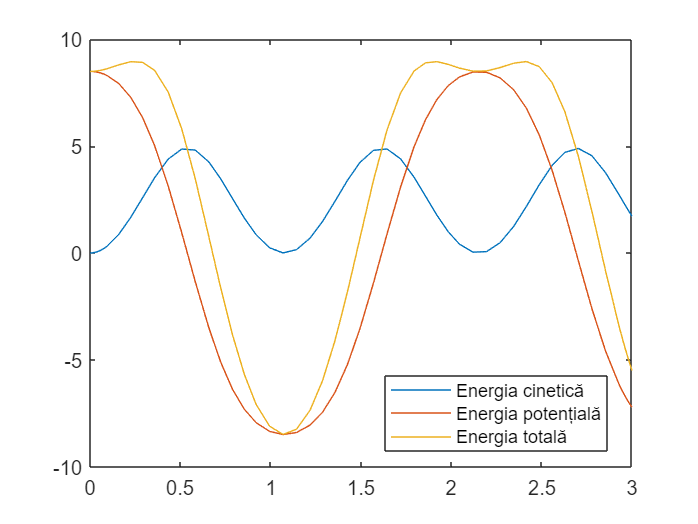


T=1/2*m.*v;
V=m*g.*r_y;
E=T+V;

plot(t,T)
hold on
plot(t,V)
plot(t,E)
hold off
legend('Energia cinetică','Energia potențială','Energia totală','Location','best')

### b) $t_f =3,\theta_0 =0,v_0 =2,l=1,m=1$

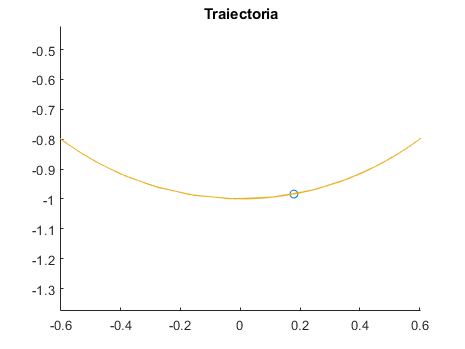

g=9.8; l=1; t_0=0; t_f=3; v_0=2; m=1;
theta_0=0; Dtheta_0=v_0/l;

syms theta(t)

interval_timp=[t_0 t_f];
val_initiale=[theta_0 Dtheta_0];
f=-g/l.*sin(theta);
theta_eq=diff(theta,t,2)==f;
[P]=odeToVectorField(theta_eq);
M=matlabFunction(P,'vars',{'t','Y'});
[t,S]=ode45(M,interval_timp,val_initiale);
theta=S(:,1);
r_x=l.*cos(theta);
r_y=l.*sin(theta);
comet(r_y,-r_x)
title("Traiectoria")
axis equal

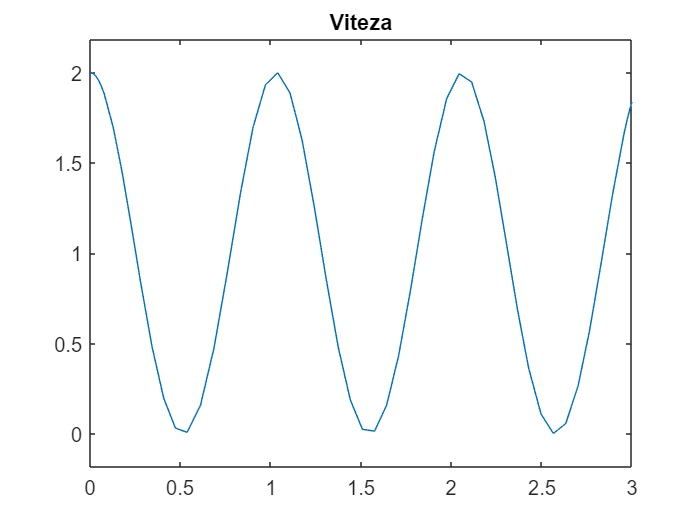


v_r=zeros(69,1);
v_t=l*S(:,2);

v=v_r.^2+v_t.^2;

plot(t,v.^1/2)
title("Viteza")
axis equal

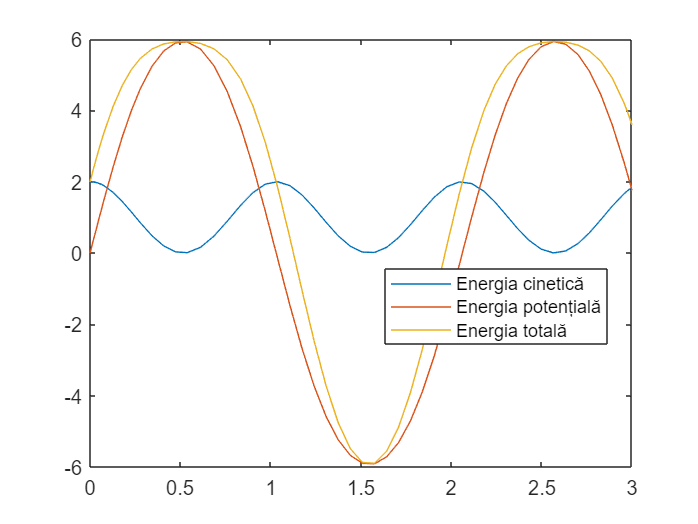


T=1/2*m.*v;
V=m*g.*r_y;
E=T+V;

plot(t,T)
hold on
plot(t,V)
plot(t,E)
hold off
legend('Energia cinetică','Energia potențială','Energia totală','Location','best')

## Problema 2

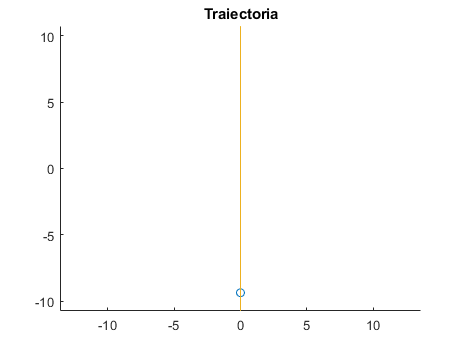

t_0=0; t_f=30; v_0=3; m=3; k=0.7;
x_0=0; Dx_0=v_0;

syms x(t)

interval_timp=[t_0 t_f];
val_initiale=[x_0 Dx_0];
f=-k/m^2.*x;
x_eq=diff(x,t,2)==f;
[P]=odeToVectorField(x_eq);
M=matlabFunction(P,'vars',{'t','Y'});
[t,S]=ode45(M,interval_timp,val_initiale);
x=S(:,1);
y=zeros(73,1);
comet(y,-x)
title("Traiectoria")
axis equal

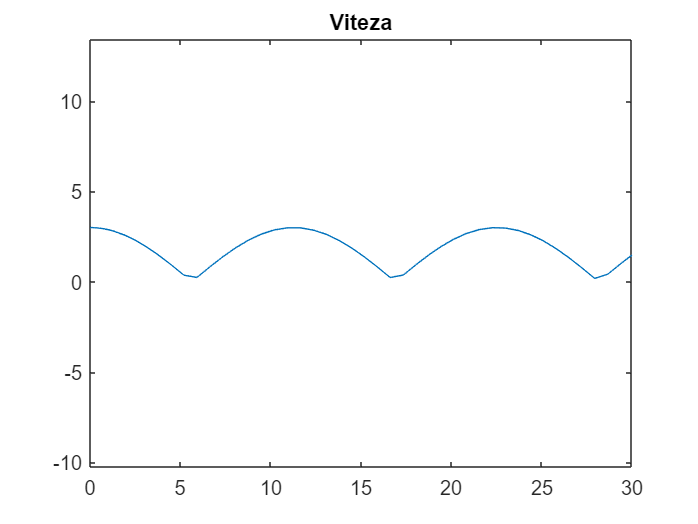


v=S(:,2);
plot(t,abs(v))
title("Viteza")
axis equal